Load the data

addpath('graphics')
addpath('data')
addpath('subfunctions')

load gd
etData

etData =            viewPos_fr_XYZ: [4950x3 double]
      vorTargetPos_fr_XYZ: [4950x3 double]
        leftEyePos_fr_XYZ: [4950x3 double]
           ballPos_fr_XYZ: [4950x3 double]
                   IPD_fr: [1x4950 double]
        inCalibrationQ_fr: [1x4950 logical]
      cycEyeInHead_fr_XYZ: [4950x3 double]
           viewMat_fr_4x4: {4950x1 cell}
             eventFlag_fr: {1x4950 cell}
       rightEyePos_fr_XYZ: [4950x3 double]
          eyeTimeStamp_fr: [1x4950 int64]
    calibrationPos_fr_XYZ: [4950x3 double]
           trialNumber_fr: [1x4950 int64]
             frameTime_fr: [1x4950 double]
     leftEyeInHead_fr_XYZ: [4950x3 double]
    rightEyeInHead_fr_XYZ: [4950x3 double]
    calibrationCounter_fr: [1x4950 int64]
                   IOD_fr: [1x4950 double]
                inVorQ_fr: [1x4950 logical]


Notice that the the X axis is flipped between Vizard and SMI.  We will have to account for that.

etData.cycEyeInHead_fr_XYZ(:,1) = -etData.cycEyeInHead_fr_XYZ(:,1);

During calibraiton, we had subjects fixate a series of calibration points.  The location fo the current cabliration point is stored in etData.calibrationPos_fr_XYZ. 

Lets see a quick 3D representation of what I'm talking about

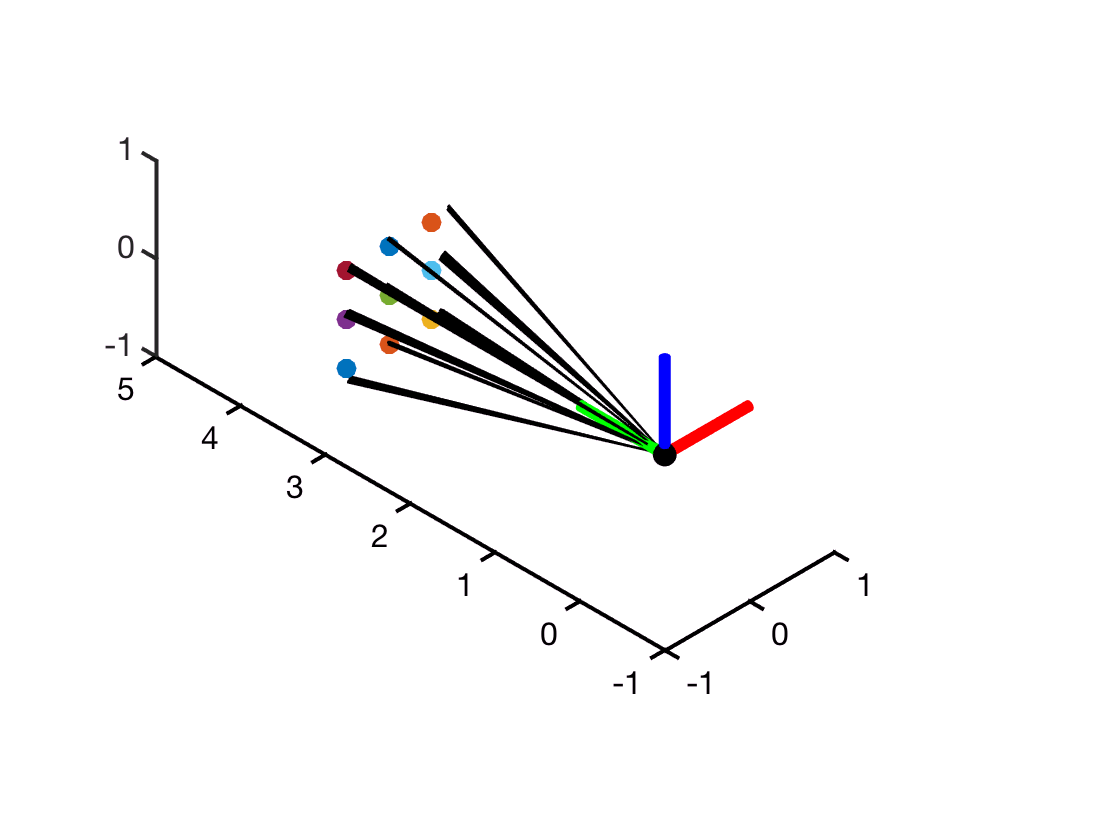

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% Plot the 3D representation

calibTrialIdx_cal = 10:18;%1:size(calElevationDeg_calPt_fr,1);

figure(2)
cla
hold on
axis equal
xlim([-1,1])
ylim([-1,5])
zlim([-1 1])
campos([-1,0,1])
camtarget([0,1,0])
drawAxis3d(1,.05)

for calibNum = 1009:1017
    idx = find(etData.trialNumber_fr==calibNum);
    
    % Scatterplot calibSphereLoc_tr_XYZ
    scatter3(etData.calibrationPos_fr_XYZ(idx ,1),...
        etData.calibrationPos_fr_XYZ(idx ,3),...
        etData.calibrationPos_fr_XYZ(idx ,2),100,'filled');
    
    cycOrigin_fr_xyz = zeros(length(etData.calibrationPos_fr_XYZ),3);
    
    Xs_fr = [etData.cycEyeInHead_fr_XYZ(idx ,1) cycOrigin_fr_xyz(idx ,1)]'*3.3;
    Ys_fr = [etData.cycEyeInHead_fr_XYZ(idx ,3) cycOrigin_fr_xyz(idx ,3)]'*3.3;
    Zs_fr = [etData.cycEyeInHead_fr_XYZ(idx ,2) cycOrigin_fr_xyz(idx ,2)]'*3.3;
    
    line(Xs_fr,Ys_fr,Zs_fr,'LineWidth',1,'Color','k');

end

We want to calculate the angular distance between the gaze vectors and these calibration targets along the azimuth and elevation. lets do that!

for frIdx = 1:length(etData.cycEyeInHead_fr_XYZ)
    
    cycEyeInHead_fr_XYZ(frIdx,:) = normalizeVector3d(etData.cycEyeInHead_fr_XYZ(frIdx,:));
    eyeToTarget_fr_XYZ(frIdx,:) =  normalizeVector3d(etData.calibrationPos_fr_XYZ(frIdx,:));
    
    angErr_fr(frIdx) = rad2deg(acos( dot(cycEyeInHead_fr_XYZ(frIdx,:)', eyeToTarget_fr_XYZ(frIdx,:)')));
    
    eihAzimuthDeg_fr(frIdx) = rad2deg(atan(cycEyeInHead_fr_XYZ(frIdx,1)./cycEyeInHead_fr_XYZ(frIdx,3)));
    targetAzimuthDeg_fr(frIdx) = rad2deg(atan(eyeToTarget_fr_XYZ(frIdx,1)./eyeToTarget_fr_XYZ(frIdx,3)));
    diffAzimuthDeg_fr(frIdx) = targetAzimuthDeg_fr(frIdx)-eihAzimuthDeg_fr(frIdx);
    
    eihElevationDeg_fr(frIdx) = rad2deg(atan(cycEyeInHead_fr_XYZ(frIdx,2)./cycEyeInHead_fr_XYZ(frIdx,3)));
    targetElevationDeg_fr(frIdx) = rad2deg(atan(eyeToTarget_fr_XYZ(frIdx,2)./eyeToTarget_fr_XYZ(frIdx,3)));
    diffElevationDeg_fr(frIdx) = targetElevationDeg_fr(frIdx)-eihElevationDeg_fr(frIdx);
    
end


While the subject was fixating each target, we pressed a button that labelled the next 200 ms with a unique "trialNumber."  The trial number corresponds to which point they were looking at, starting at trialNumber 1000 for the top-left point.  This facilitates grabbing all the frames on which the subject was looking at that point.  

So, Lets group our data by calibration target.

calibTrialValues_trIdx = unique(etData.trialNumber_fr);
calibTrialValues_trIdx = calibTrialValues_trIdx(calibTrialValues_trIdx>=1000);
calibTrialValues_trIdx = calibTrialValues_trIdx( calibTrialValues_trIdx < 5000);

for calPt = 1:numel(calibTrialValues_trIdx);
    
    trVal = calibTrialValues_trIdx(calPt);
    trialFrames_trIdx{calPt} = find(etData.trialNumber_fr==trVal);
    
    %% Now, saved by frame
    calibSphereLoc_tr_XYZ(calPt,:) = etData.calibrationPos_fr_XYZ(trialFrames_trIdx{calPt}(1),:);
    len = length(eihAzimuthDeg_fr(trialFrames_trIdx{calPt}));
    eihAzimuthDeg_calPt_fr(calPt,1:len) = eihAzimuthDeg_fr(trialFrames_trIdx{calPt});
    calAzimuthDeg_calPt_fr(calPt,1:len) = targetAzimuthDeg_fr(trialFrames_trIdx{calPt});
    
    eihElevationDeg_calPt_fr(calPt,1:len) = eihElevationDeg_fr(trialFrames_trIdx{calPt});
    calElevationDeg_calPt_fr(calPt,1:len) = targetElevationDeg_fr(trialFrames_trIdx{calPt});
    
    meanAngErr_calPt(calPt) = nanmean(angErr_fr(trialFrames_trIdx{calPt}));
    stdAngErr_calPt(calPt) = nanstd(angErr_fr(trialFrames_trIdx{calPt}));
end

Lets now average over the angular distances for each calibration point

eihAzimuthDegMean_trIdx = nanmean(eihAzimuthDeg_calPt_fr,2);
calAzimuthDegMean_trIdx= nanmean(calAzimuthDeg_calPt_fr,2);
diffAzimuthDeg_trIdx= nanmean(diffAzimuthDeg_fr(trialFrames_trIdx{calPt}));

eihElevationDegMean_trIdx = nanmean(eihElevationDeg_calPt_fr,2);
calElevationDegMean_trIdx= nanmean(calElevationDeg_calPt_fr,2);
diffElevationDeg_trIdx = nanmean(diffElevationDeg_fr(trialFrames_trIdx{calPt}));

Lets draw a 2D representeation where 

X = degrees azimuth

Y = degrees elevation.

For each trial, draw calibration spheres in one color. For each trial, draw average gaze location spheres in another color. Use text() to write the angular error above each target (with 2 units of precision).

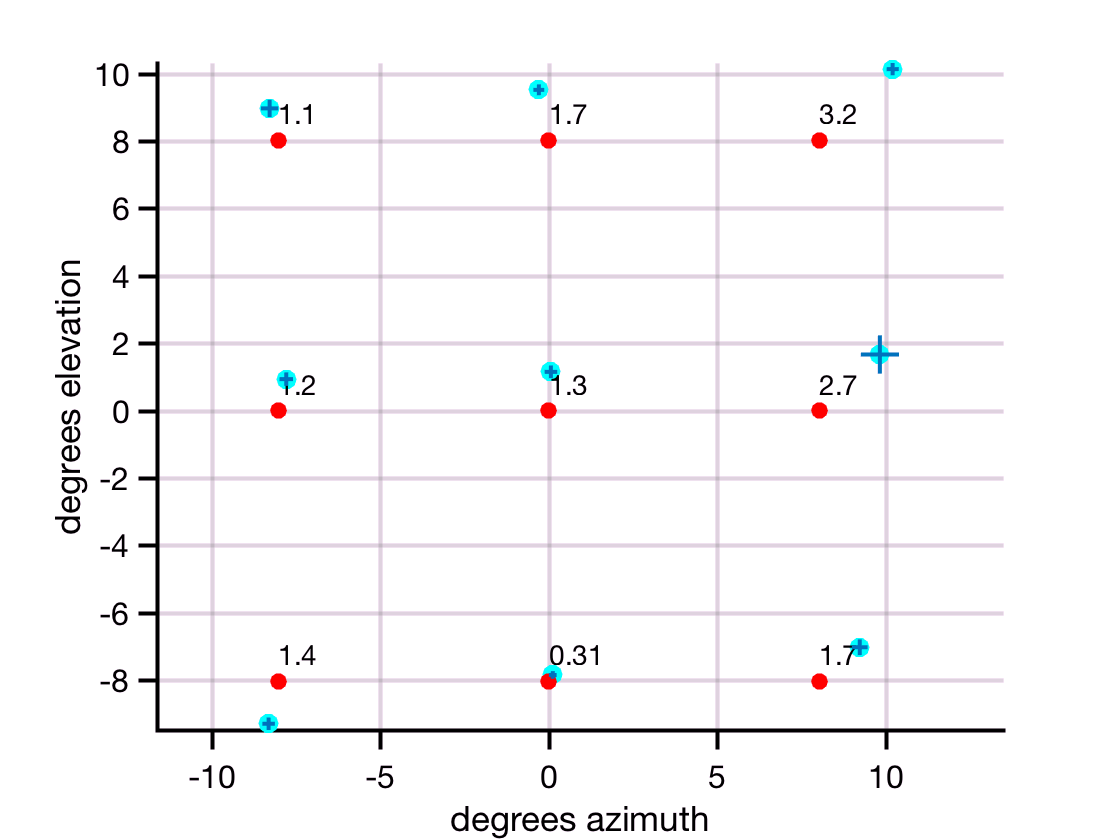

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


figure(3)
cla

hold on
axis equal
grid on
xlabel('degrees azimuth')
ylabel('degrees elevation')

scatter(eihAzimuthDegMean_trIdx(calibTrialIdx_cal),eihElevationDegMean_trIdx(calibTrialIdx_cal),100,'oc','filled')
scatter(calAzimuthDegMean_trIdx(calibTrialIdx_cal),calElevationDegMean_trIdx(calibTrialIdx_cal),70,'or','filled')

for calPt = calibTrialIdx_cal
   
    text(calAzimuthDegMean_trIdx(calPt),calElevationDegMean_trIdx(calPt)+.8,mat2str(meanAngErr_calPt((calPt)),2));
    
    line([eihAzimuthDegMean_trIdx(calPt)-stdAngErr_calPt(calPt),eihAzimuthDegMean_trIdx(calPt)+stdAngErr_calPt(calPt)],...
        [eihElevationDegMean_trIdx(calPt),eihElevationDegMean_trIdx(calPt)]);
    
    line([eihAzimuthDegMean_trIdx(calPt),eihAzimuthDegMean_trIdx(calPt)],...
        [eihElevationDegMean_trIdx(calPt)-stdAngErr_calPt(calPt),eihElevationDegMean_trIdx(calPt)+stdAngErr_calPt(calPt)]);
    
end